# Simulating a 28 GHz Antenna for a UAV

## Load the data

The data for this lab was generously donated by Vasilii Semkin of VTT and taken from the paper:

- W Xia,V. Semkin, M. Mezzavilla, G. Loianno, S. Rangan, Multi-array Designs for MmWave and Sub-THzCommunication to UAVs, 2020

The paper performs EM simulations on a ciccularly polarized 28 GHz antenna mounted to the bottom of a commercial DJI Matrice 100 quadrocopter. An image of the drone with the antenna and its pattern is shown in the following picture.

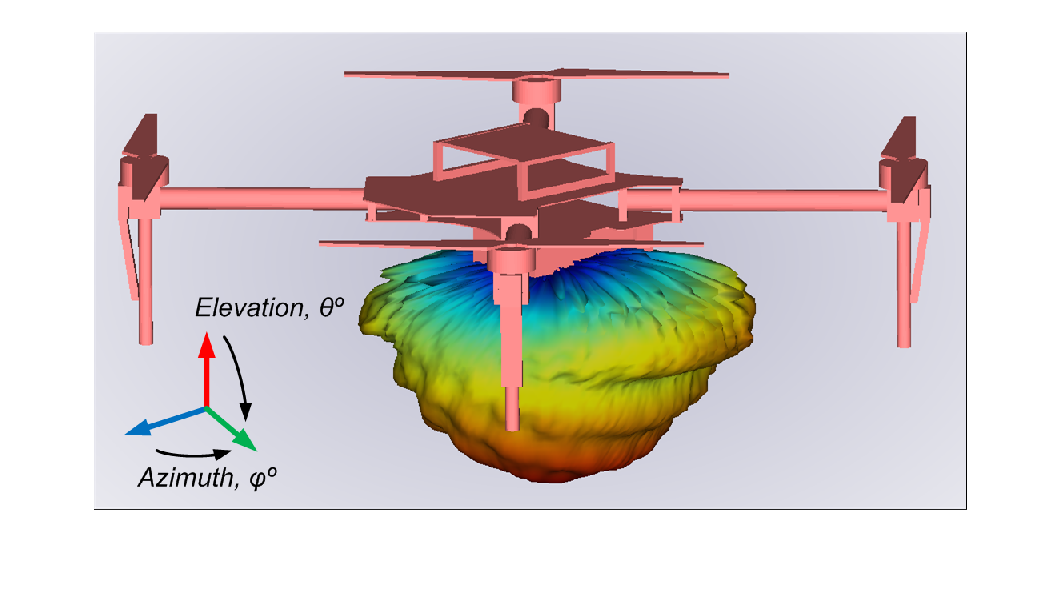

A = imread('CP_patch_downwards_m100_3D_coord.png');
imshow(A, 'InitialMagnification', 80);

We will first load the data with the following command. 

load patch_bottom_data.mat
data_table(1:5,:)

ans = 5×9 table
    x_AngleIndex    Elevation    Azimuth    Frequency    TotVReal    TotVImag    TotHReal    TotHImag       Var9   
    ____________    _________    _______    _________    ________    ________    ________    ________    __________

         0             -90          0        2.8e+10     0.018862    0.037489     0.02257    0.019296    {0×0 char}
         1             -90          2        2.8e+10     0.019638     0.03814    0.021898    0.017976    {0×0 char}
         2             -90          4        2.8e+10     0.020391    0.038744    0.021199    0.016634    {0×0 char}
         3             -90          6        2.8e+10     0.021118    0.039301    0.020475    0.01

## Reading and the data table

el = data_table(:,"Elevation").Variables;
az = data_table(:,"Azimuth").Variables;

el = -el;

## Getting the E-field

realh= data_table(:,"TotHReal").Variables;
imgh = data_table(:,"TotHImag").Variables;

realv= data_table(:,"TotVReal").Variables;
imgv = data_table(:,"TotVImag").Variables;

EH = realh + i*imgh ;
EV = realv + i*imgv ;

Epow = (abs(EH)).^2 + (abs(EV)).^2  ;

## Computing  the directivity

% computing the constant c 

c = mean(cos(deg2rad(el)))/mean(Epow.*cos(deg2rad(el)));

% printing directivity matrix in dBi

dir = log10(c*Epow)

dir =    -2.6152
   -2.6152
   -2.6152
   -2.6152
   -2.6152
   -2.6152
   -2.6152
   -2.6152
   -2.6152
   -2.6152


## Plotting the 3D antenna pattern

elvals = (-90:2:90)';
azvals = (-180:2:180)';
nel = length(elvals);
naz = length(azvals);


%creating the directivity matrix

dirMat = reshape(dir,naz,nel);
dirMat = (dirMat)';

dirMat = circshift(dirMat,90);
dirMat = flipud(dirMat)

dirMat =    -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152   -2.6152
    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313    0.7313

To plot the antenna pattern, I have a  CustomAntennaObject in MATLAB's phased array toolbox. 

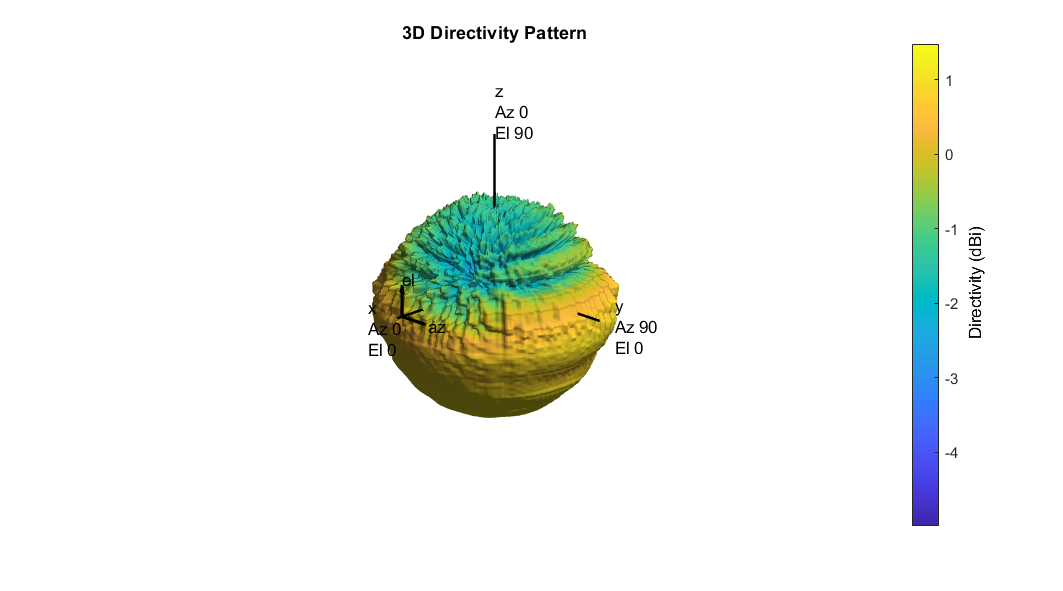

%creating the custom antenna 

phasePattern = zeros(size(dirMat));

ant_custom = phased.CustomAntennaElement(...
    'AzimuthAngles', azvals, 'ElevationAngles', elvals, ...
    'MagnitudePattern', dirMat, ...
    'PhasePattern', phasePattern);


fc = 28e9;

ant_custom.pattern(fc)


% physical constants

fc = 2.3e9;     % Carrier frequency
vp = physconst('lightspeed'); % speed of light
lambda = vp/fc;   % wavelength

## Plots

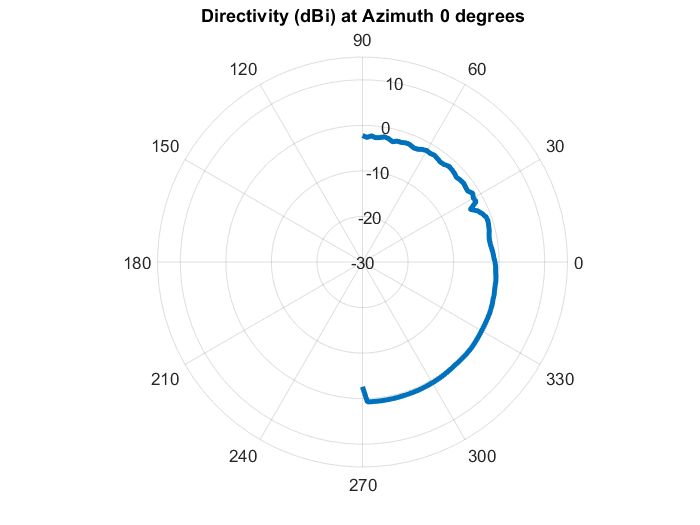

% we take the 1st column in the dirMat for the directivity values as this
% is the closest to the zero azimuth angle

figure;
polarplot(deg2rad(elvals), dirMat(:,1),'LineWidth', 3);
rlim([-30, 15]);
title('Directivity (dBi) at Azimuth 0 degrees')

## Computing the half-power beamwidth

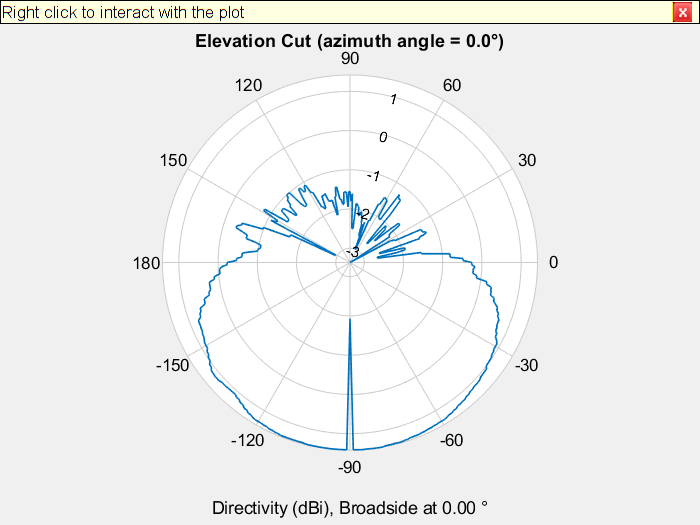

clf('reset')

patternElevation(ant_custom,fc) % to see the plot of elevation cut 


dircut = patternElevation(ant_custom,fc);

% This returns the directivity along eleation angles elcut

elcut = (-180:180);

[~,ind_max] = max(dircut(dircut>0)); %this will get the index with the maximum directivity value

ind_array = []; %creating an empty array to store the index 

%now we store the angles that have directivity values in the 3dBi range of
%the peak value 

for i = 1:size(dircut)
    if dircut(ind_max)- dircut(i) <= 3 
        
        ind_array = [ind_array i];
    else break                       % we break out when the value falls below 3dBi difference
    end
end


% we subtract the corner points angles to get the hpbw

hpbw = elcut(max(ind_array)) - elcut(min(ind_array));

fprintf("The half power bandwidth is %d degrees",hpbw)

The half power bandwidth is 89 degrees

***Comment*** :

 Not sure if the hpbw values is correct. It could be more than 89 degrees as this is only caused by the sharp drop in the directivity at -90 degrees .. If we observe the plot we have another lob from -90  to around +120 degrees ..which means the hpbw could be 150 degrees ?

## Computing power fractions.

% Calculating the total radiated power 
tot_pow = 0 ;
for i = 1: size(Epow)
    tot_pow = tot_pow + Epow(i);
end



% calulating power in upper hemisphere 

% we know the upper hemisphere is represesnted in the first half of the
% data points in .mat file 

up_pow = 0;

for i = 1: (size(Epow)-1)/2
    up_pow = up_pow + Epow(i);
end


frac = up_pow/tot_pow;

fprintf("The fraction of power radiated in the upper hemisphere is %f ",frac)

The fraction of power radiated in the upper hemisphere is 0.010750 

## Computing the path loss along a path

 UAV RX flying from (0,0,30) to (500,0,30) in a linear path and  TX is at (0,0,0). 

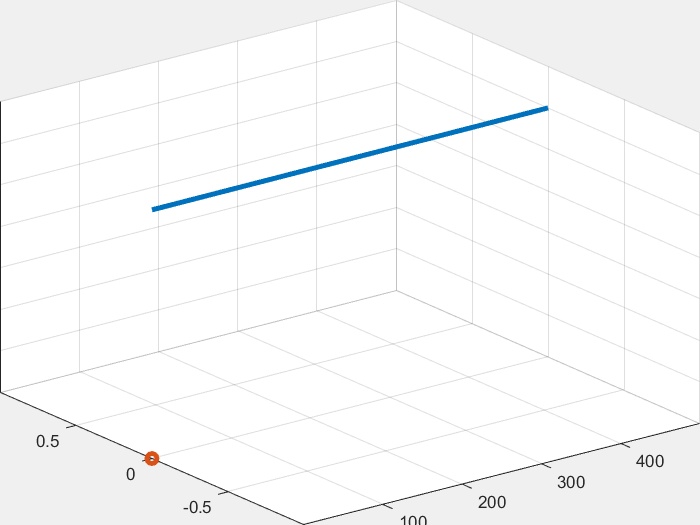

% Define the linear path
npts = 100;
xstart = [0 0 30]'; 
xend = [500 0 30]';
t = linspace(0,1,npts);
X = xstart*(1-t) + xend*t;

% Ploting  the path in 3D along with the location of the TX at the origin

plot3(X(1,:), X(2,:), X(3,:), 'Linewidth', 3);
hold on;
plot3(0, 0, 0, 'o', 'Linewidth', 3);
grid();
hold off;



[azpath, elpath, dist] = cart2sph(X(1,:), X(2,:), X(3,:));
azpath = rad2deg(azpath);
elpath = rad2deg(elpath);

% Computing the free space path loss along the path 
plOmni = fspl(dist, lambda);

% we create the 
% interpolation object.
F = griddedInterpolant({(-90:2:90),(-180:2:180)},dirMat);

% computing the directivity using the object
dirPath = F(elpath,azpath);

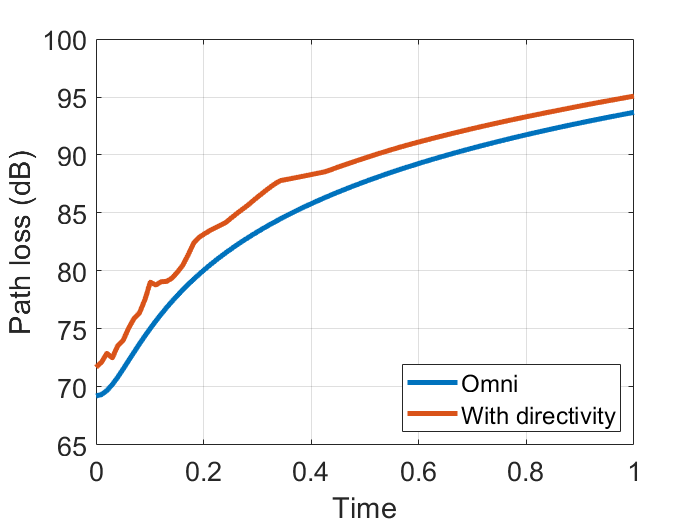


% Computing the total path loss including the directivity
plDir = plOmni - dirPath;

% Ploting the path loss over time

figure;
plot(t, [plOmni; plDir]', 'Linewidth', 3);
grid();
set(gca, 'Fontsize', 16);
legend('Omni', 'With directivity', 'Location', 'SouthEast');
xlabel('Time');
ylabel('Path loss (dB)');